## Example init

clc
clear all

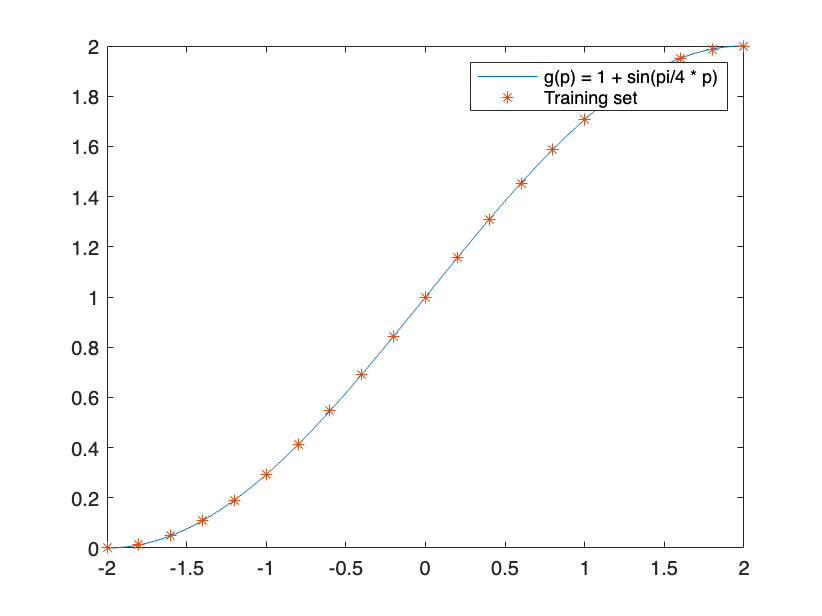

% Data
p = linspace(-2, 2, 400);
g_p = 1+sin(pi/4*p);
polynomial = [p ; g_p]';
plot(polynomial(:,1), polynomial(:,2))
train_index = -2 : 0.2 : 2;
train_data = 1+sin(pi/4*train_index);
hold on 
plot(linspace(-2, 2, length(train_data)), train_data, '*')
hold off
legend('g(p) = 1 + sin(pi/4 * p)','Training set'); 

% Funtion definition
function y = purelin(x)
    y = x; % Linear
end

function y = purelind(x)
    y = 1; % Linear derivative
end

function y = logsig(x)
    y = 1 ./ (1 + exp(-x)); % Sigmoid
end

function y = logsigd(x)
    y = x .* (1 - x); % Sigmoid derivative
end

% Network
learning_rate = 0.1;
layers = [1 2 1];

transferFuncs = {
    @(x) logsig(x);
    @(x) purelin(x)  
};
transferFuncsDeriv = {
    @(x) logsigd(x);
    @(x) purelind(x)  
};

disp('Initial W values')

Initial W values


W1 = [-0.27; -0.41]

W1 =    -0.2700
   -0.4100


W2 = [0.09 -0.17]

W2 =     0.0900   -0.1700


disp('Initial B values')

Initial B values


B1 = [-0.48; -0.13]

B1 =    -0.4800
   -0.1300


B2 = 0.48

B2 = 0.4800


weights = {W1; W2};
biases = {B1; B2};

## Learning example

% Starting with the 16th
input = train_index(16);
target = train_data(16);

trainSpecific(input, target, weights, biases, transferFuncs, transferFuncsDeriv, learning_rate);

function [weights, biases, error] = trainSpecific(input, target, weights, biases, transferFuncs, transferFuncsDeriv, learning_rate)
    
    a1 = transferFuncs{1}(weights{1} * input + biases{1});
    a2 = transferFuncs{2}(weights{2} * a1 + biases{2});
    
    error = target - a2;
    
    s2 = -2 * transferFuncsDeriv{2}(a2) .* (target -  a2);
    s1 = transferFuncsDeriv{1}(a1) .* (weights{2}' * s2);
    
    weights{2} = weights{2} - learning_rate * s2 * a1';
    weights{1} = weights{1} - learning_rate * s1 * input';
    % disp('w2');
    % disp(weights{2});
    % disp('w1');
    % disp(weights{1});

    biases{2} = biases{2} - learning_rate * s2;
    biases{1} = biases{1} - learning_rate * s1;
    % disp('b2');
    % disp(biases{2});
    % disp('b1');
    % disp(biases{1});
end

function [weights, biases, error] = train(input, target, weights, biases, transferFuncs, transferFuncsDeriv, learning_rate)
    % Forward
    activations = cell(length(weights), 1);
    output = input;
    
    for i = 1:length(weights)
        z = weights{i} * output + biases{i};
        output = transferFuncs{min(i, length(transferFuncs))}(z); % Apply tf
        activations{i} = output;
        % fprintf('a%i =', i);
        % disp(output);
    end
    
    error = target - output;
    % disp('error')
    % disp(error);
    
    % Backward
    num_layers = length(weights);
    
    % Initialize gradients for all layers
    gradients.dWeights = cell(num_layers, 1);
    gradients.dBiases = cell(num_layers, 1);
    
    % Compute output layer s
    % s^M = -2 * F'^M(n^M) * (t - a)
    s = -2 * transferFuncsDeriv{end}(output) .* (target - output);
    % fprintf('s%i =', num_layers);
    % disp(s);
    
    % Backpropagate through hidden layers
    for m = num_layers:-1:1
        % Previous layer activations (or input if first layer)
        if m == 1
            prev_activation = input;
        else
            prev_activation = activations{m - 1};
        end
    
        % Compute weight and bias gradients
        gradients.dWeights{m} = s * prev_activation';
        gradients.dBiases{m} = s;
        
        % Propagate error backward if not input layer
        if m > 1
            % s^m = F'^m(n^m) * (W^{m+1})^T * s^{m+1}
            activation_deriv = transferFuncsDeriv{m - 1}(activations{m - 1});
            s = activation_deriv .* (weights{m}' * s);
    
            % fprintf('s%i =', m-1);
            % disp(s);
        end
    end
    
    % Update weights & bias
    for i = 1:length(weights)
        weights{i} = weights{i} - learning_rate * gradients.dWeights{i};
        biases{i} = biases{i} - learning_rate * gradients.dBiases{i};
    
        % fprintf('W%i =', i);
        % disp(weights{i});
        % 
        % fprintf('B%i =', i);
        % disp(biases{i});
    end
end

## Training

% Divide training and test set
data = polynomial(:,2);
numSamples = length(data);

% Generate random shuffled indices
indices = randperm(numSamples);

% Split percentages
numTrain = floor(0.8 * numSamples);  % Training 80%
numTest = floor(0.2 * numSamples);   % Testing 20%

% Split the data
trainIdx = indices(1:numTrain);
testIdx = indices(numTrain + 1:end);

trainData = data(trainIdx);
testData = data(testIdx);

weights = {
    -1 + 2 * rand(layers(2), layers(1));
    -1 + 2 * rand(layers(3), layers(2))
}

weights = 2×1 cell array
    {2×1 double      }
    {[-0.1662 0.2858]}



biases = {
    -1 + 2 * rand(layers(2), 1);
    -1 + 2 * rand(layers(3), 1)
}

biases = 2×1 cell array
    {2×1 double}
    {[  0.3504]}



learning_rate = 1e-4

learning_rate = 1.0000e-04

% Train in 100 epochs
max_epoch = 3000;
error_history = zeros(1,length(max_epoch));
for n = 1:max_epoch
    epoch_error_history = zeros(1,length(trainData));
    for i = 1:length(trainData) % Loop over training samples
        [weights, biases, error] = train(trainIdx(i), trainData(i), weights, biases, transferFuncs, transferFuncsDeriv, learning_rate);
        epoch_error_history(i) = error^2;
    end
    epoch_error = mean(epoch_error_history);
    error_history(n) = epoch_error;
end

final_error = error_history(end)

final_error = 0.0211

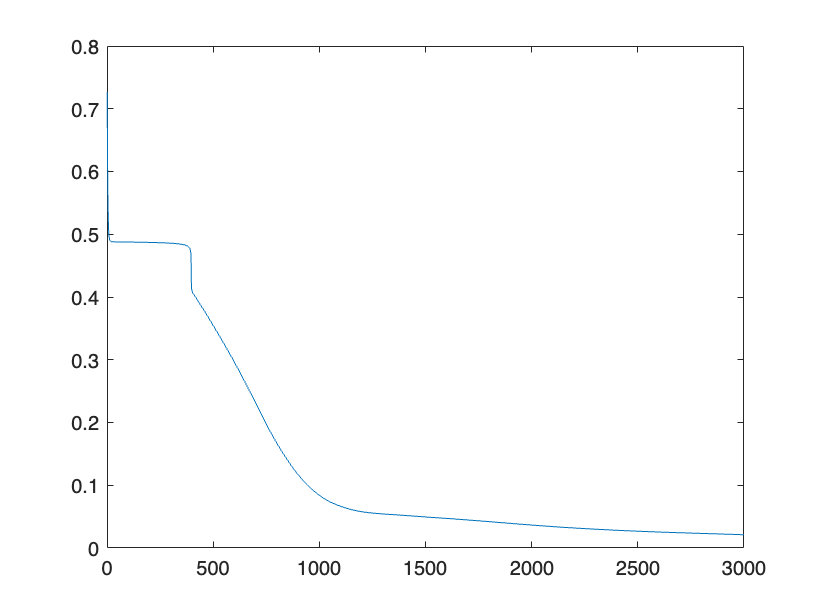


plot(error_history);

% Test
% Inicializar vectores
inputs = testIdx;                  % Entradas del conjunto de prueba
target_outputs = testData;           % Salidas deseadas
mlp_outputs = zeros(size(inputs));  % Salidas del MLP

% Generar salidas del MLP para cada entrada del conjunto de prueba
for i = 1:length(inputs)
    % Forward (from train specific function)
    a1 = transferFuncs{1}(weights{1} * inputs(i) + biases{1});
    a2 = transferFuncs{2}(weights{2} * a1 + biases{2});

    mlp_outputs(i) = a2;
end

train_error = (target_outputs(end) - a2)^2

train_error = 2.0885e-04

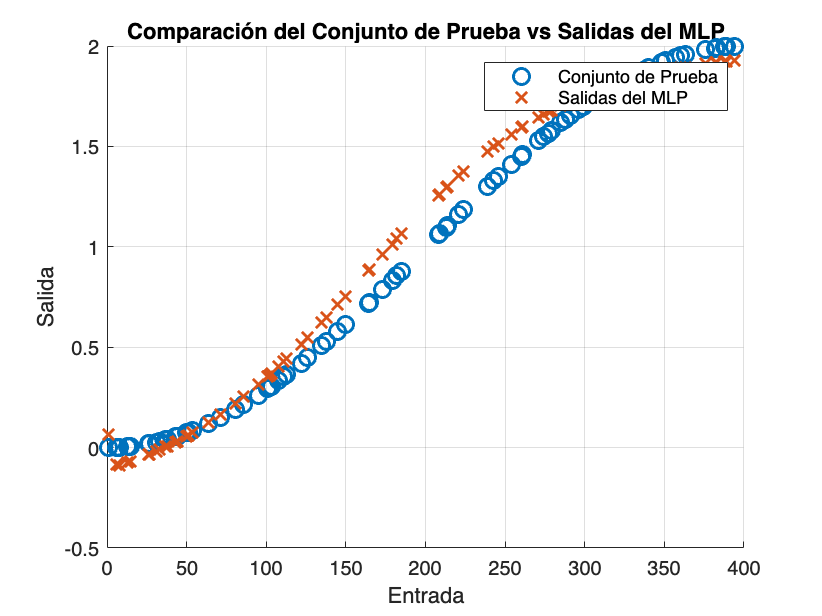


% Crear la gráfica
figure;
hold on;

% Graficar los valores del conjunto de prueba (círculos sin relleno)
plot(inputs, target_outputs, 'o', 'MarkerSize', 8, 'LineWidth', 1.5, ...
    'DisplayName', 'Conjunto de Prueba');

% Graficar las salidas del MLP (cruces)
plot(inputs, mlp_outputs, 'x', 'MarkerSize', 8, 'LineWidth', 1.5, ...
    'DisplayName', 'Salidas del MLP');

% Configurar la gráfica
title('Comparación del Conjunto de Prueba vs Salidas del MLP');
xlabel('Entrada');
ylabel('Salida');
legend('show');
grid on;
hold off;

## Test Class

transferFuncs = [2 1];

% Create MLP network
mlp = mlpNetwork(layers, transferFuncs);
disp('MLP created successfully')

MLP created successfully


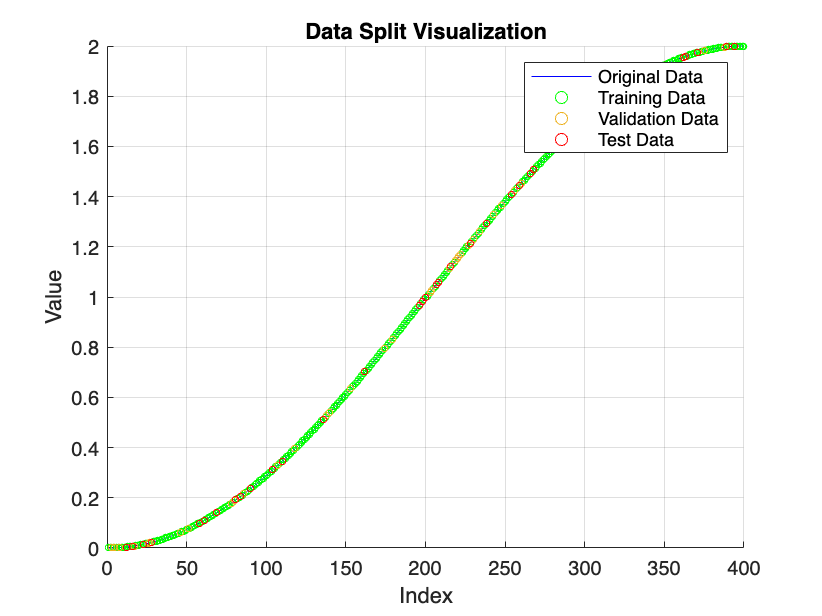


% Get data sets
[trainSet, valSet, testSet] = mlp.generateSets(polynomial);

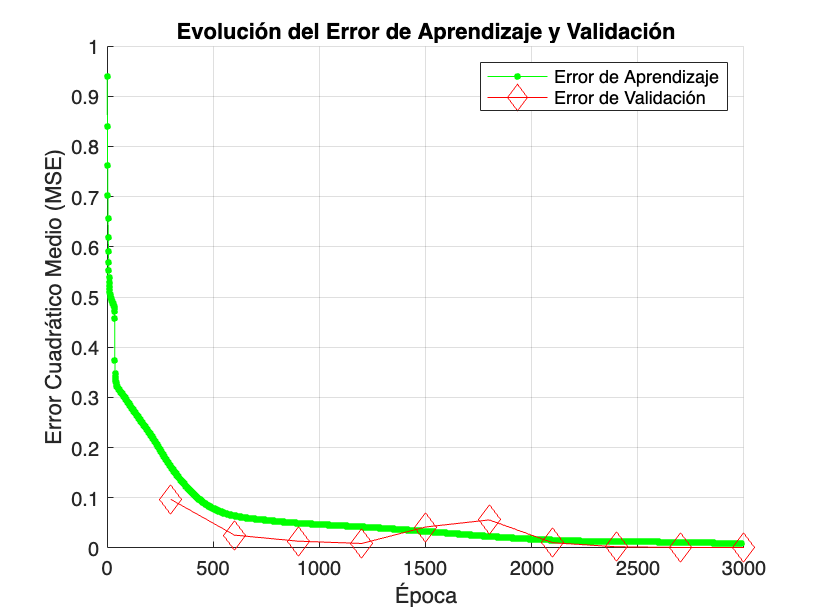

% Train MLP network
maxEpochs = 3000;           % Maximum number of epochs
learningRate = 1e-4;        % Delta value 1e-2 to 1e-5
errorTrain = 1e-4;          % Accuracy
epochVal = maxEpochs*0.1;   % How many epochs during the learning process will be a validation
numVal = 5;                 % The number of consecutive increments of validation error validation error to trigger early stopping
numberOfBatches = 1;      % Number of batches to train

batch = 1;                  % Batch number
stopCode = 0;               % Code indicating early stopping
while (stopCode ~= 1 && batch <= numberOfBatches)
    [mlp, stopCode] = mlp.train( ...
        trainSet, ...
        valSet, ...
        learningRate, ...
        maxEpochs, ...
        errorTrain, ...
        epochVal, ...
        numVal...
    );
    batch = batch + 1;
end

% Plot error
mlp.graphErroHistory(epochVal);

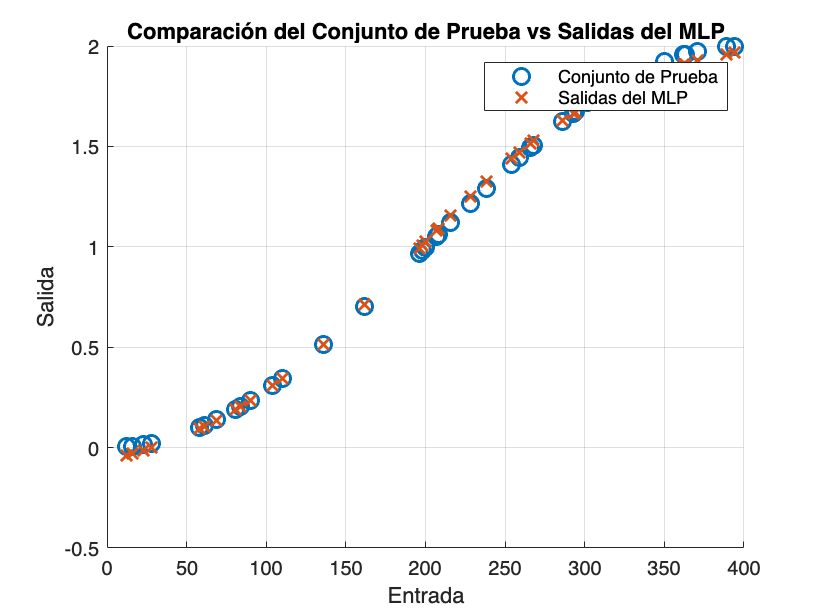


% Plot test
mlp.graphTestSet(testSet);